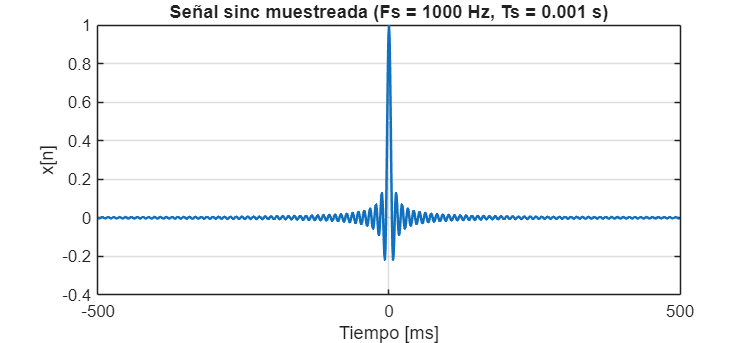

%% FFT, FFTSHIFT y réplicas (señal sinc, versión limpia)
% Autor: Lucas Novales y Javier Matanza
clear; close all; clc

% === Parámetros de muestreo ===
Fs = 1000;              % Frecuencia de muestreo [Hz]
Ts = 1/Fs;              % Periodo de muestreo [s]
T  = 1;                 % Duración total [s]
t  = 0:Ts:T-Ts;         % Instantes de muestreo
N  = length(t);         % Número de muestras
df = Fs/N;              % Resolución en frecuencia [Hz]

% === Señal sinc centrada ===
t0 = t -T/2;           
B  = 200;               % Controla el ancho de banda
x  = sinc(B*t0);        % sinc(x) = sin(pi*x)/(pi*x)

% === FFT ===
X  = fft(x);
Xc = fftshift(X);

% === Vectores de frecuencia ===
f_nocenter = (0:N-1)*df;        % 0 ... Fs-df
f_center   = -Fs/2:df:Fs/2-df;  % -Fs/2 ... +Fs/2-df

%% 1) Señal en el dominio temporal
figure('Position',[100 100 1100 500]);
plot(t0*1e3, x, 'LineWidth', 1.5);
grid on
xlabel('Tiempo [ms]');
ylabel('x[n]');
title(sprintf('Señal sinc muestreada (Fs = %d Hz, Ts = %.3g s)', Fs, Ts));

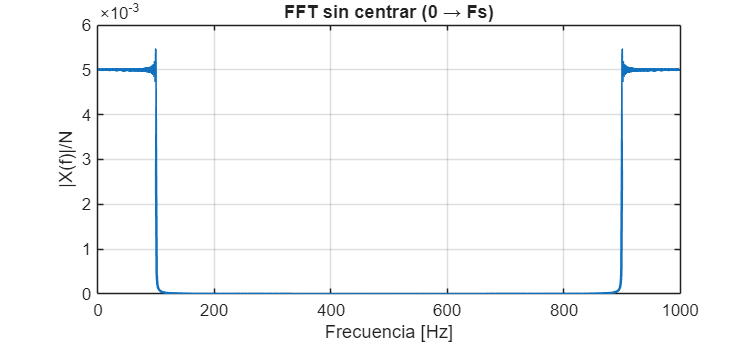


%% 2) FFT sin centrar (0 → Fs)
figure('Position',[100 100 1100 500]);
plot(f_nocenter, abs(X)/N, 'LineWidth', 1.5);
grid on
xlabel('Frecuencia [Hz]');
ylabel('|X(f)|/N');
title('FFT sin centrar (0 → Fs)');
xlim([0 Fs]);

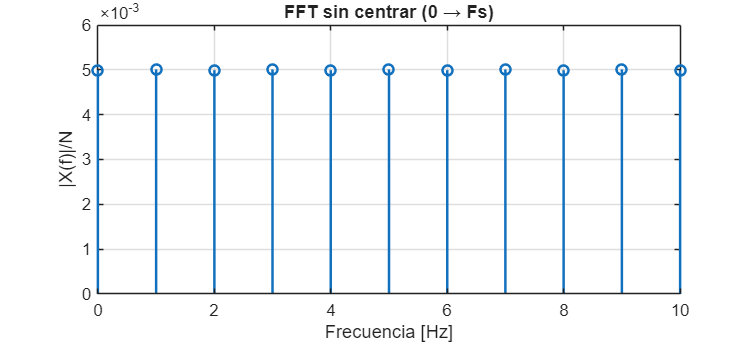


%% 2) FFT sin centrar (0 → Fs)
figure('Position',[100 100 1100 500]);
stem(f_nocenter, abs(X)/N, 'LineWidth', 1.5);
grid on
xlabel('Frecuencia [Hz]');
ylabel('|X(f)|/N');
title('FFT sin centrar (0 → Fs)');
xlim([0 10]);
grid on
xlabel('Frecuencia [Hz]');
ylabel('|X(f)|/N');
title('FFT sin centrar (0 → Fs)');
xlim([0 10]);

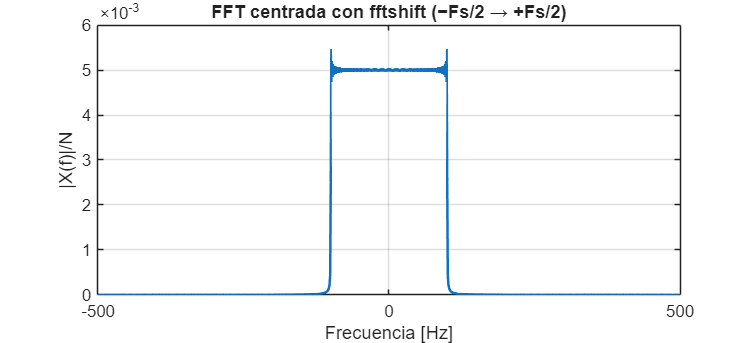


%% 3) FFT centrada (-Fs/2 → +Fs/2)
figure('Position',[100 100 1100 500]);
plot(f_center, abs(Xc)/N, 'LineWidth', 1.5);
grid on
xlabel('Frecuencia [Hz]');
ylabel('|X(f)|/N');
title('FFT centrada con fftshift (−Fs/2 → +Fs/2)');
xlim([-Fs/2 Fs/2]);

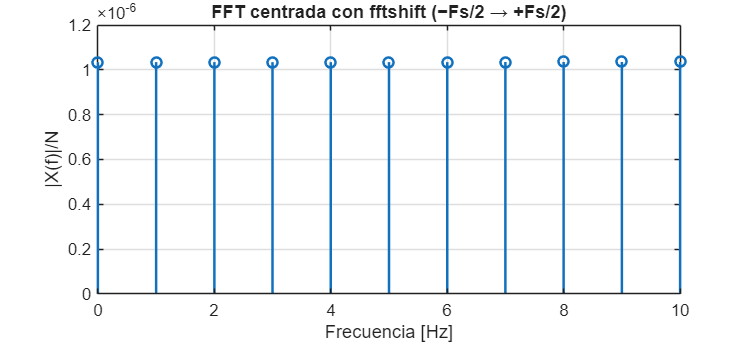


%% 3) FFT centrada (-Fs/2 → +Fs/2)
figure('Position',[100 100 1100 500]);
stem(f_center, abs(X)/N, 'LineWidth', 1.5);
grid on
xlabel('Frecuencia [Hz]');
ylabel('|X(f)|/N');
title('FFT centrada con fftshift (−Fs/2 → +Fs/2)');
xlim([0 10]);

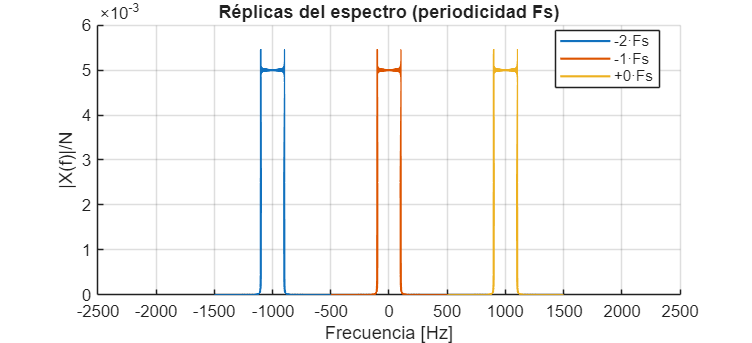



%% 4) Réplicas espectrales (periodicidad Fs)
figure('Position',[100 100 1100 500]); hold on
for k = -1:1
    plot(f_center + k*Fs, abs(Xc)/N, 'LineWidth', 1.3);
end
grid on; hold off
xlabel('Frecuencia [Hz]');
ylabel('|X(f)|/N');
title('Réplicas del espectro (periodicidad Fs)');
xlim([-2.5*Fs 2.5*Fs]);
legend(arrayfun(@(k) sprintf('%+d·Fs',k), -2:2, 'UniformOutput', false), ...
       'Location','best');